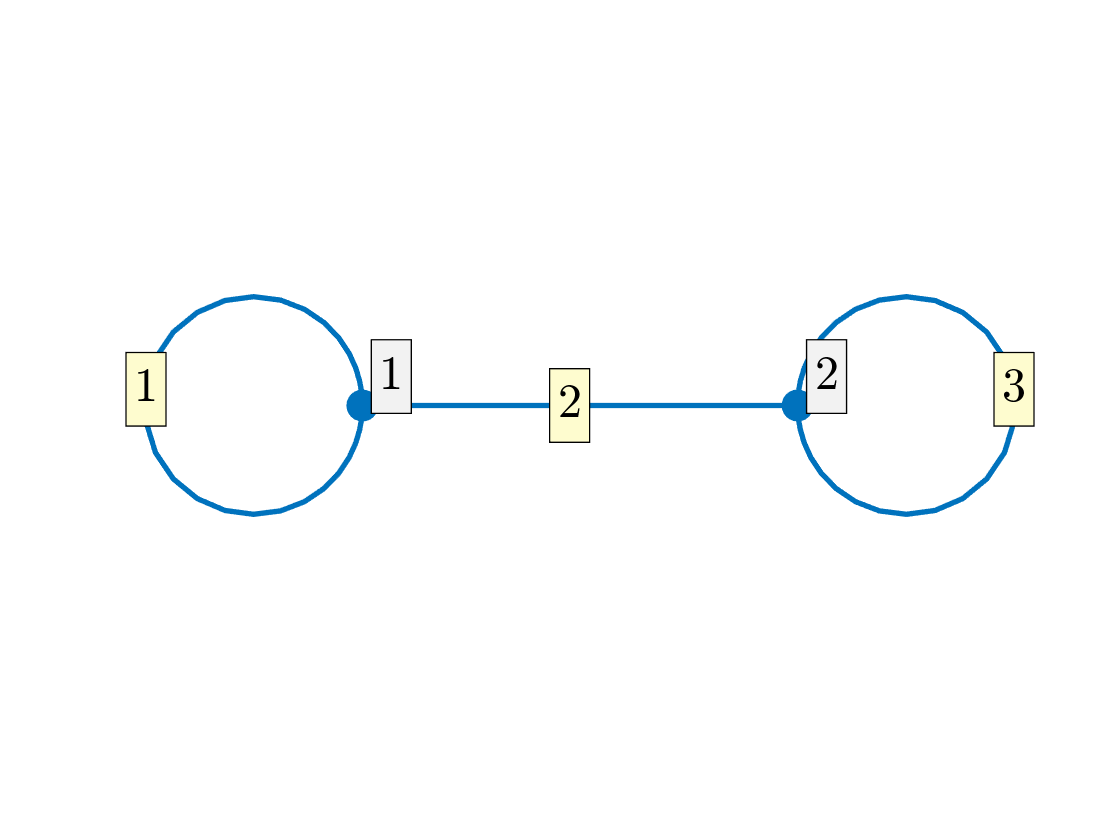

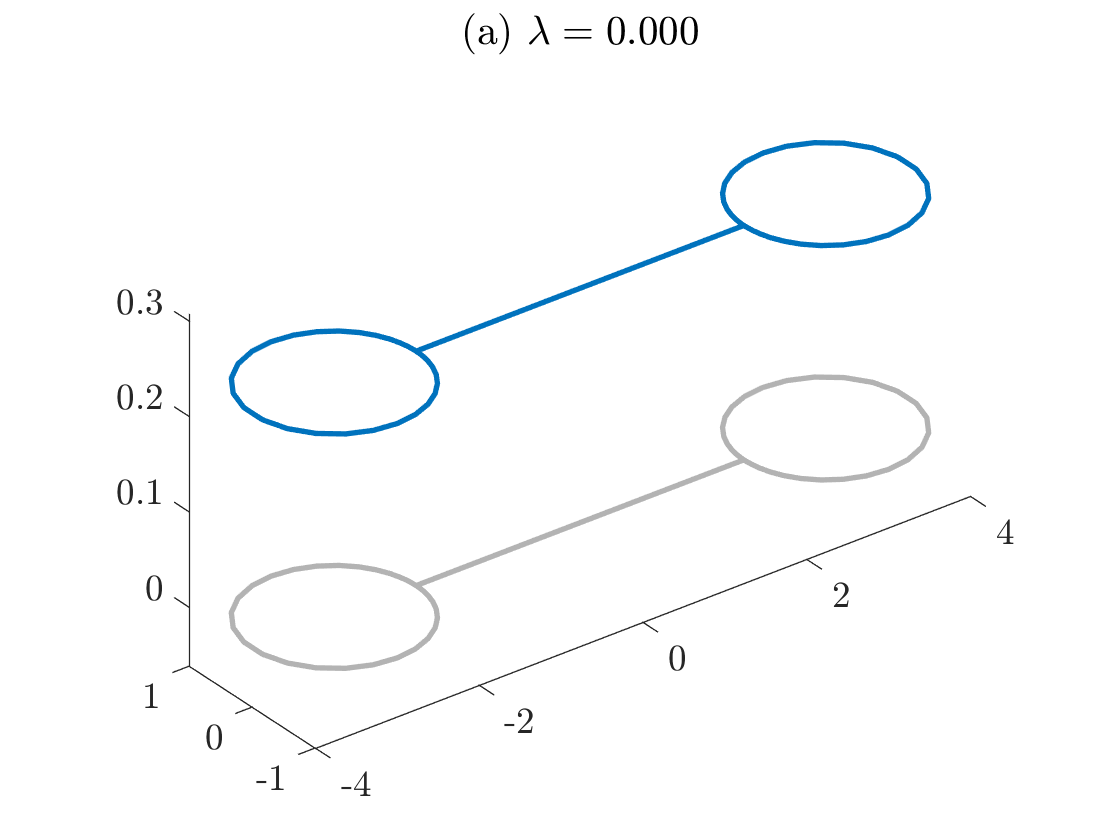

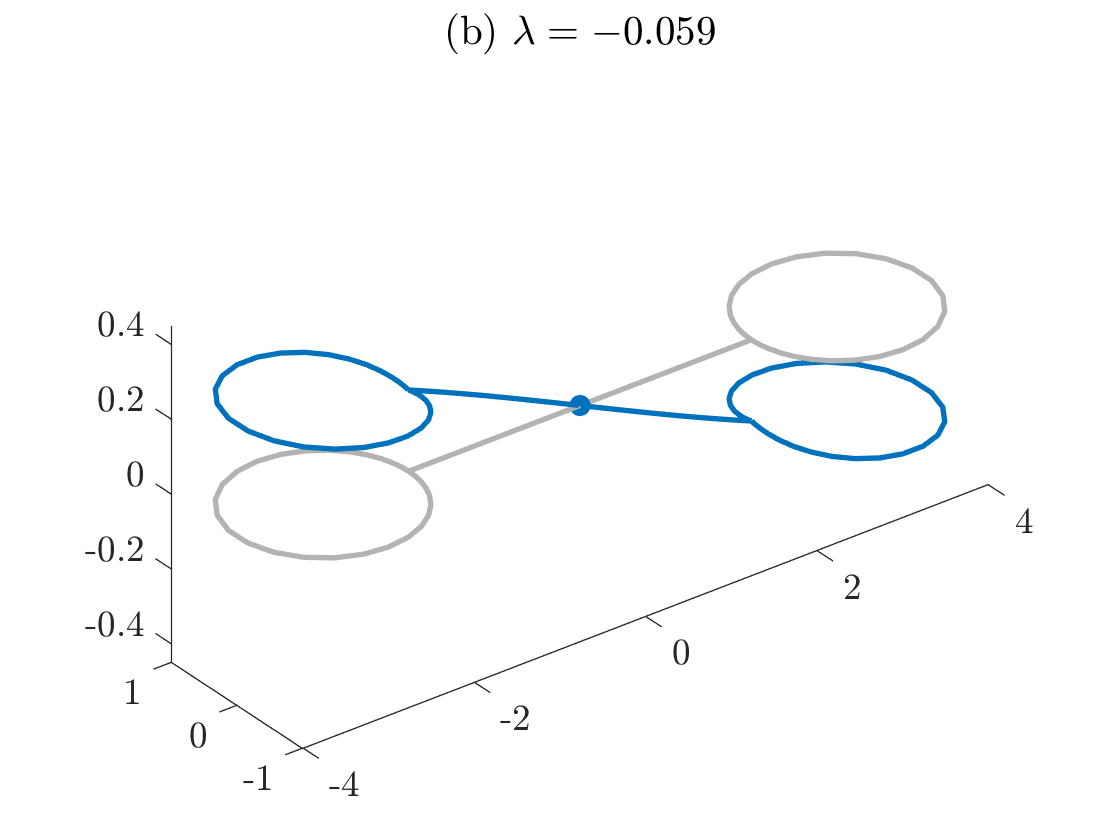

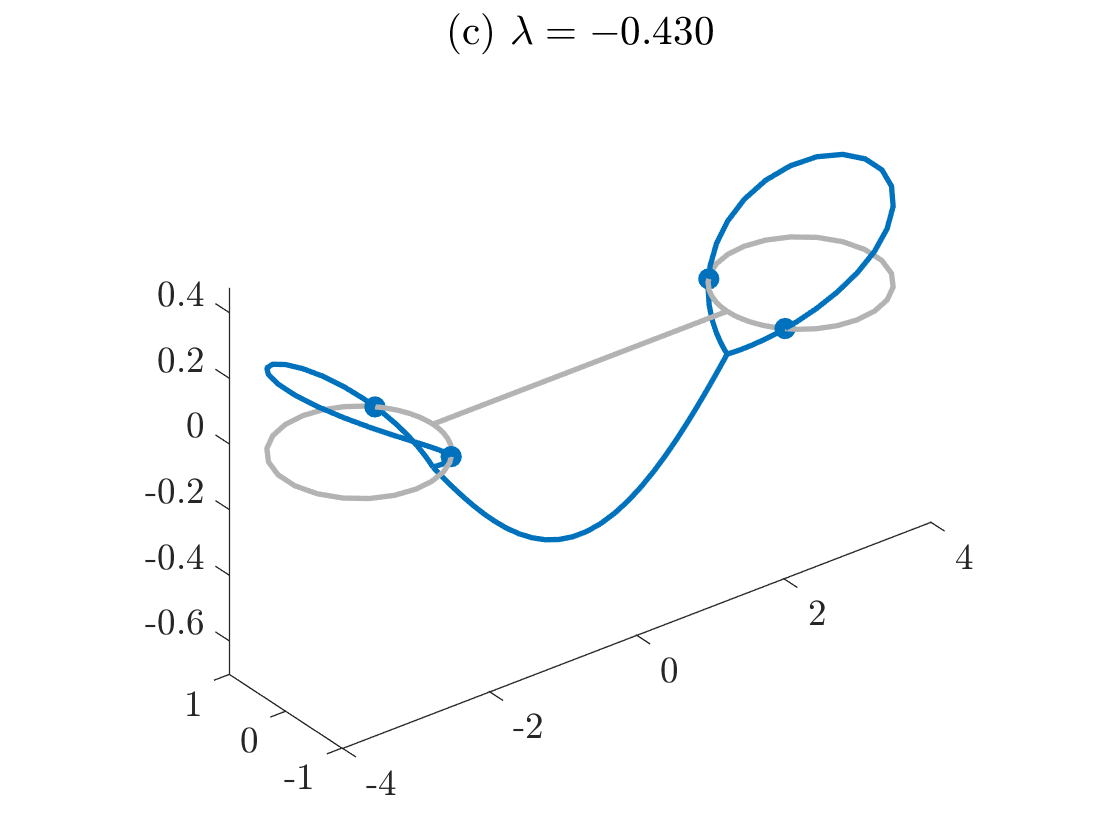

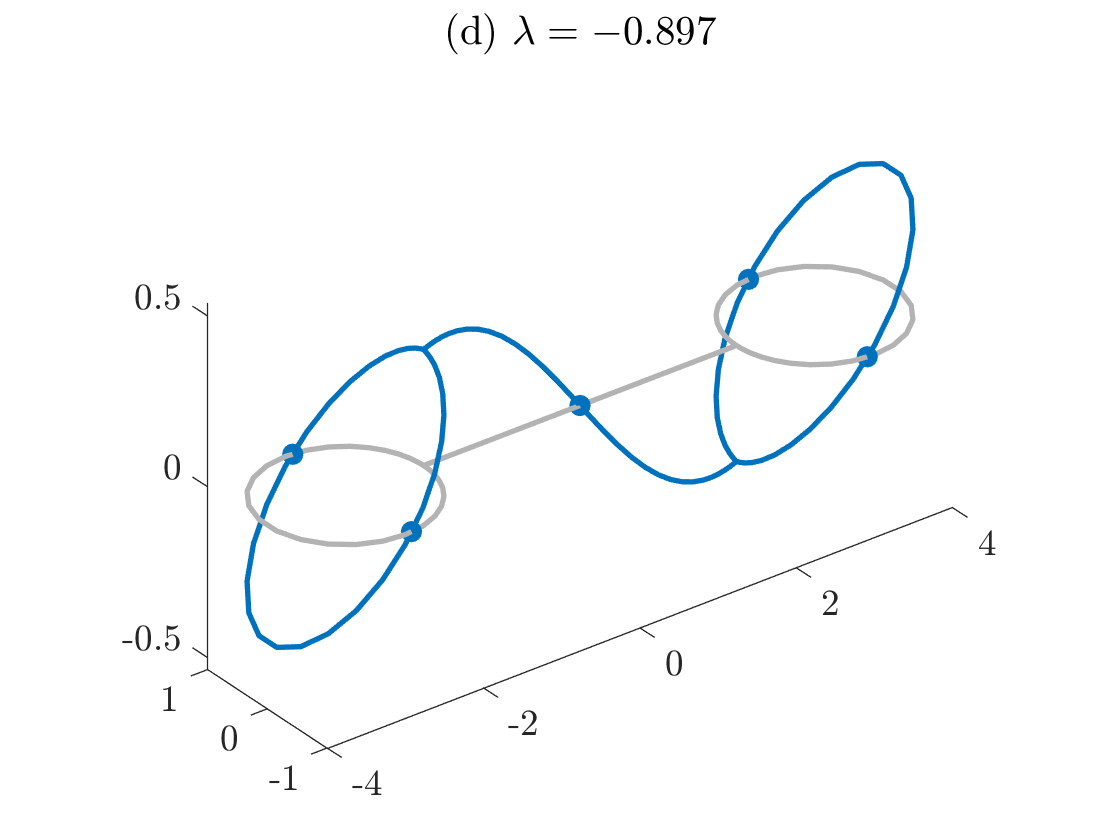

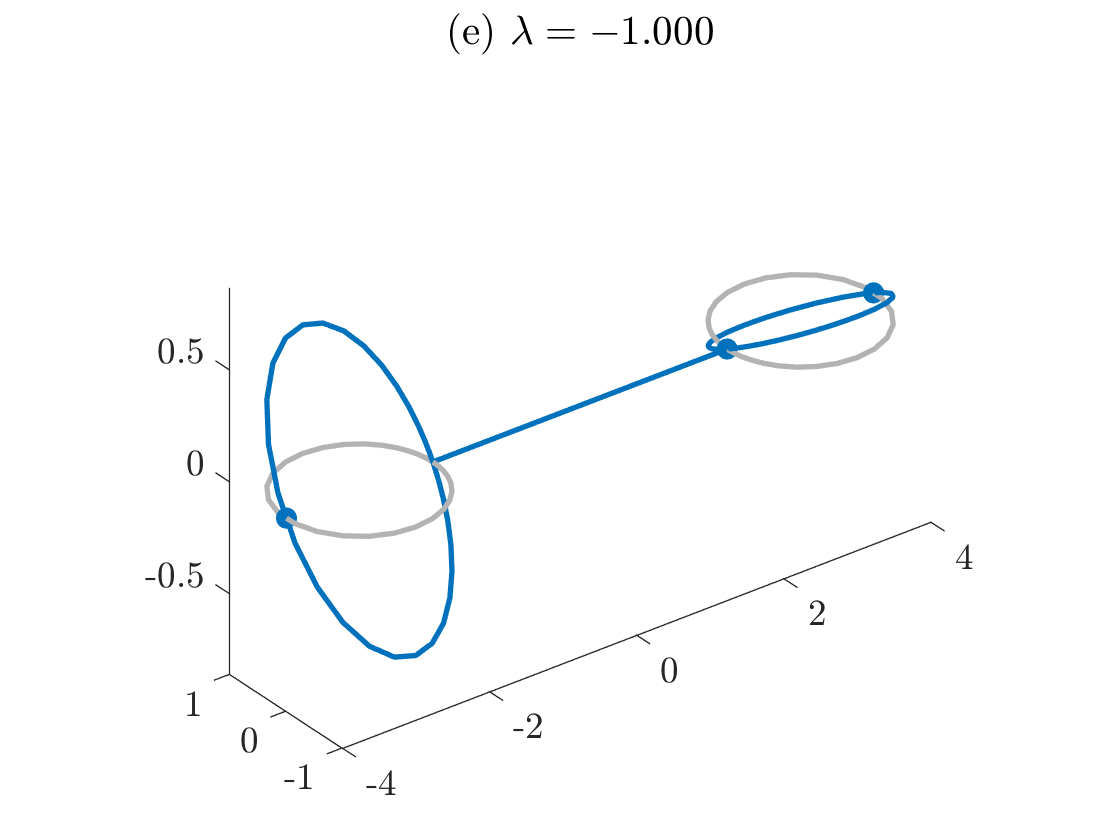

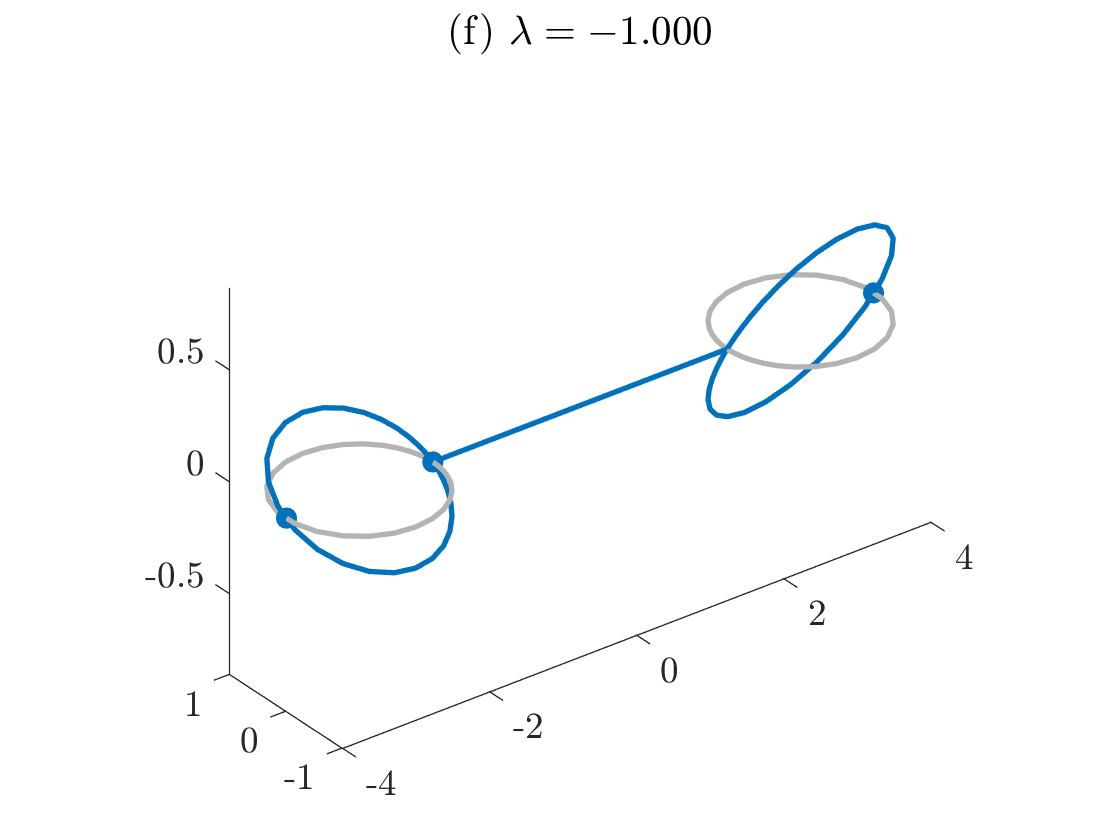

Saved to directory data\dumbbell\017.
Run number is 17.


tag='dumbbell';
Phi = quantumGraphFromTemplate('dumbbell','discretization','Chebyshev','nx',32);

nToPlot=4;
nDoubles=1;
nTriples=0;
diagramNumber=eigenfunctionsSaveData(Phi,tag,nToPlot,nDoubles,nTriples);

options=continuerSet([],'LambdaThresh',-1,'NThresh',6,'plotFlag',false);
eigNumber=1;
[bn1,bl1]=continueFromEig(tag,diagramNumber,eigNumber,options);

N threshold crossed.
Branch number 1.
Data saved to directory data\dumbbell\017\branch001.
Branching Bifurcation at solution number 4.
Branching Bifurcation at solution number 6.
Branching Bifurcation at solution number 9.
Branching Bifurcation at solution number 11.


[bn2,bl2]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(1),1,options);

Lambda threshold crossed.
Branch number 2.
Data saved to directory data\dumbbell\017\branch002.
No branching bifurcations found.


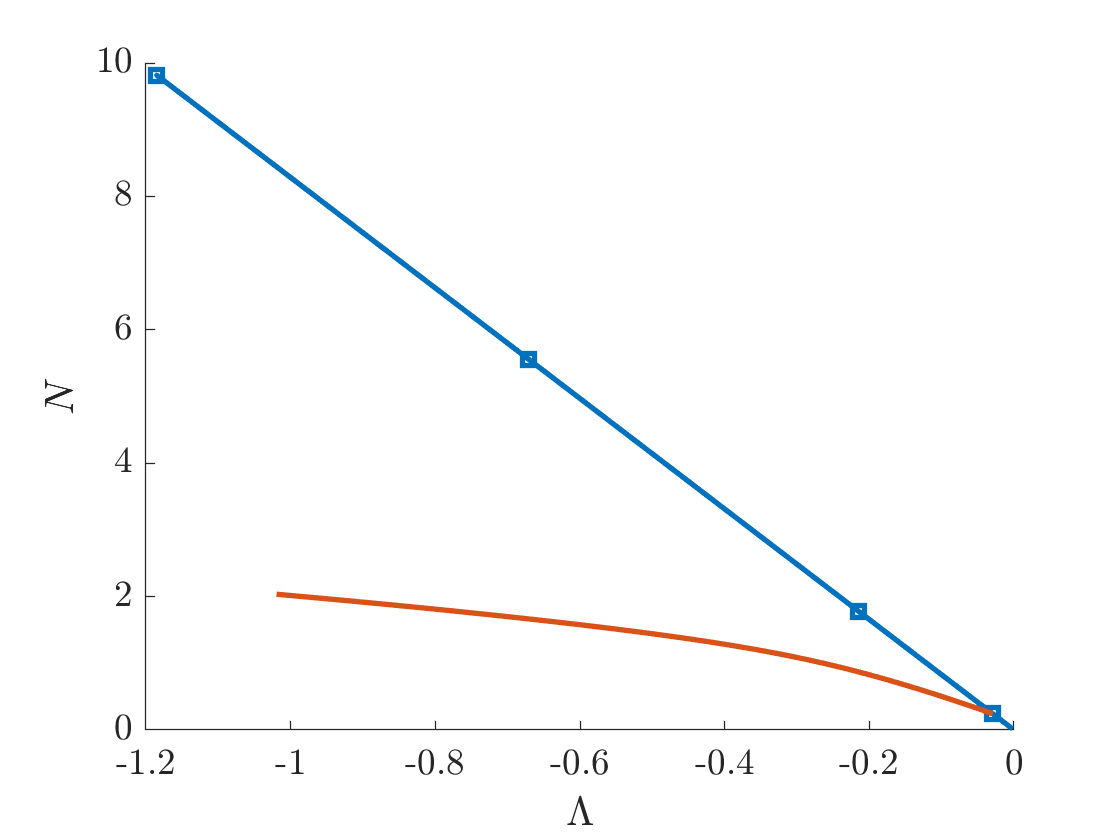

bifurcationDiagram(tag,diagramNumber)

[bn3,bl3]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),1,options);

Lambda threshold crossed.
Branch number 3.
Data saved to directory data\dumbbell\017\branch003.
Branching Bifurcation at solution number 12.


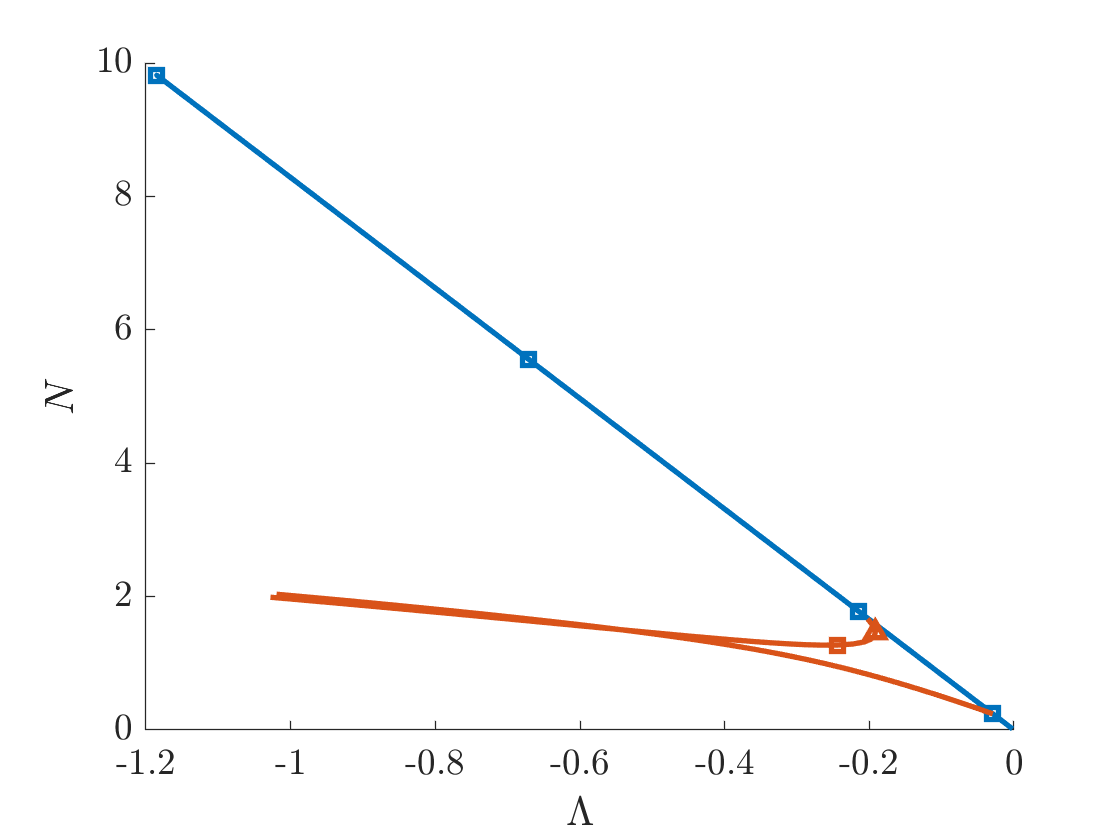

bifurcationDiagram(tag,diagramNumber)

[bn4,bl4]=continueFromBranchPoint(tag,diagramNumber,bn1,bl1(2),-1,options);

Lambda threshold crossed.
Branch number 4.
Data saved to directory data\dumbbell\017\branch004.
No branching bifurcations found.


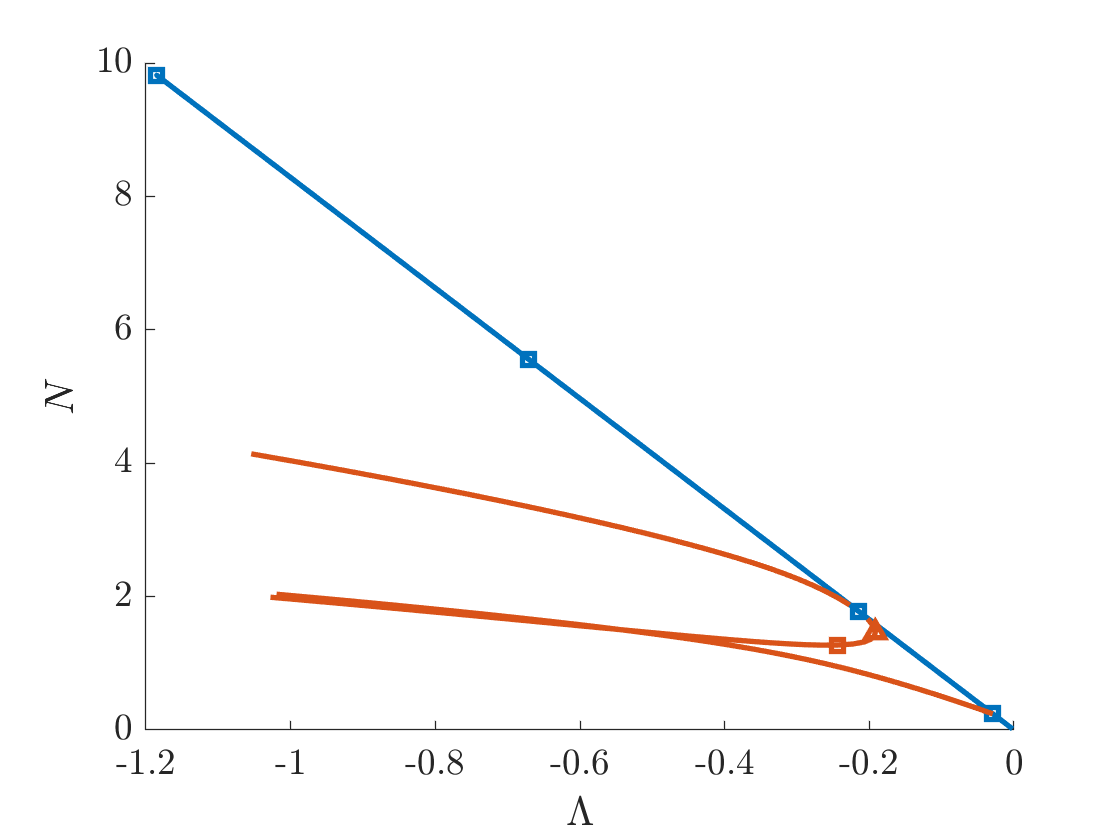

bifurcationDiagram(tag,diagramNumber)

[bn5,bl5]=continueFromBranchPoint(tag,diagramNumber,bn3,bl3(1),1,options);
bifurcationDiagram(tag,diagramNumber)

Lambda0=-4;
edges=[1 2];
signs=[1 1];
filenumber=saveHighFrequencyStandingWave(tag,diagramNumber,Lambda0,edges,signs);

options=continuerSet(options,'LambdaThresh',-4.1,'NThresh',9);
[bn6,bl6]=continueFromSaved(tag,diagramNumber,filenumber,-1,options);
bifurcationDiagram(tag,diagramNumber)

% NExtra=2; LambdaExtra=2;
% [bn7,bl7]=continueFromEnd(tag,diagramNumber,bn1,'last',NExtra,LambdaExtra,options);
% bifurcationDiagram(tag,diagramNumber)

% rmBranch(tag,diagramNumber,'last')
% bifurcationDiagram(tag,diagramNumber)

% rmBranch(tag,diagramNumber,bn5)
% bifurcationDiagram(tag,diagramNumber)

plotSolution(tag,diagramNumber,bn3,15)

% plotSolution(tag,diagramNumber,bn6,'last')


